# 第三次实验

## 实验七-1（2）

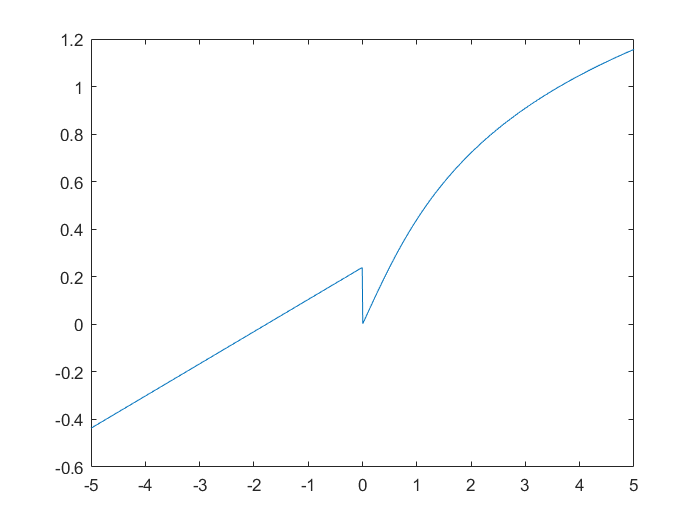

x = linspace(-5,5,1000);
y = [];
for x0=x
    if x0<=0
        f = (x0+sqrt(pi))/exp(2);
        y = [y, f];
    else
        f = 1/2*log(x0+sqrt(1+x0^2));
        y = [y, f];
    end
end

plot(x,y)

## 实验七-2（1）

clear

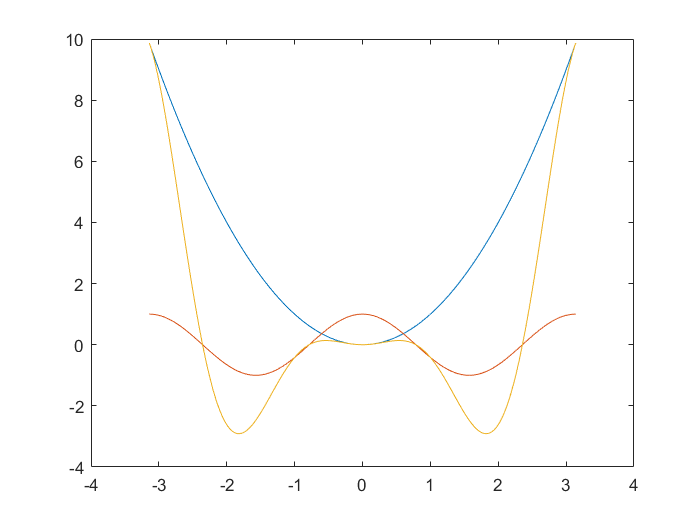

x = linspace(-pi,pi,1000);
y1 = x.^2;
y2 = cos(2.*x);
y3 = y1 .* y2;

plot(x,y1);
hold on
plot(x,y2);
plot(x,y3);
hold off

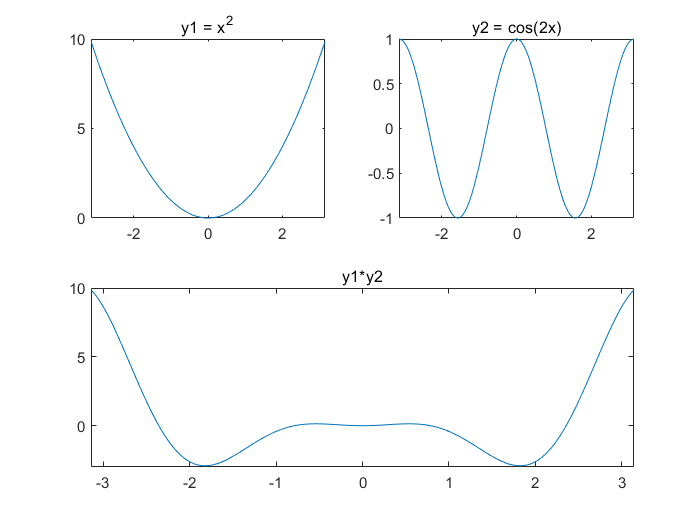

subplot(2,2,1);
plot(x,y1);
title('y1 = x^2');axis([-pi pi 0 10 ]);

subplot(2,2,2);
plot(x,y2);
title('y2 = cos(2x)');axis([-pi pi -1 1 ]);

subplot(2,1,2);
plot(x,y3);
title('y1*y2');axis([-pi pi -3 10 ]);

## 实验七-3 绘制三维曲线

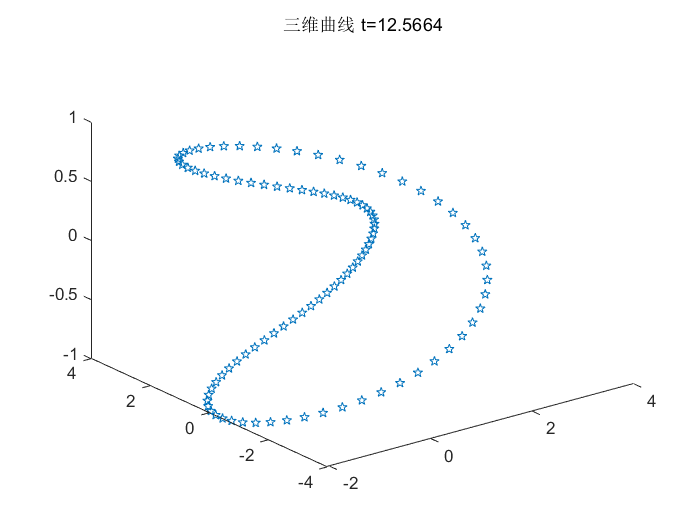

clear
t = linspace(0, 4*pi, 100);
x = [];
y = [];
z = [];
figure
filename = 'testnew.gif';
for t0 = t
   x = [x, (2+cos(t0./2)).*cos(t0)];
   y = [y, (2+cos(t0./2)).*sin(t0)];   
   z = [z, sin(t0./2)];
   plot3(x, y, z, 'p');
   title(['三维曲线 t=' num2str(t0)]);
   drawnow
   frame = getframe(gcf);
   im = frame2im(frame);
   [imind,cm] = rgb2ind(im,256);
   if t0 == 0
       imwrite(imind,cm,filename,'gif', 'Loopcount',inf);
   else
       imwrite(imind,cm,filename,'gif','WriteMode','append');
   end
end

## 实验七-4

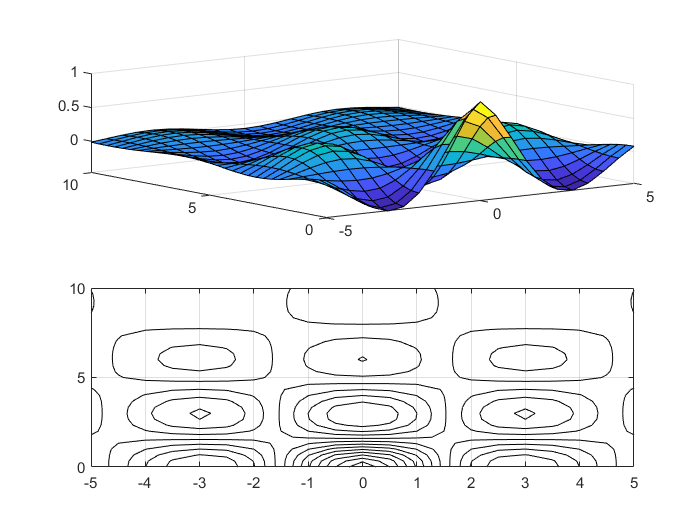

x = linspace(-5,5,21);
y = linspace(0,10,31);
[x, y] = meshgrid(x,y);
z = cos(x).*cos(y).*exp(-sqrt(x.^2+y.^2)/4);
subplot(2,1,1);
surf(x,y,z);
subplot(2,1,2);
contour3(x,y,z,12,'k');